# PARTE 1: Laboratorio 1 MyS

Se busca graficar las respuestas de lazo abierto y lazo cerrado para las funciones indicadas en el enunciado. El paso a paso realizado para obtener la Función de Transferencia $H(s)$ se muestra en el informe. 

## Función 1

En primer lugar se debe obtener la respuesta de lazo abierto y lazo cerrado del sistema. Dada la naturaleza de este último, ya se tiene la función racional correspondiente al lazo abierto, por lo que utilizando la función **feedback()** se debe obtener la función racional correspondiente al lazo cerrado.

% Se limpian las variables guardadas en el Workspace
clearvars;
% Se define el modelo para las funciones de transferencia
s = tf('s');
% Se define la función de Transferencia H(s) de la ecuación 1
H1 = (4*s) / (3*s + 1);
% Lazo abierto corresponde a H1(s)
H1A = H1

H1A =
 
    4 s
  -------
  3 s + 1
 
Continuous-time transfer function.
Model Properties


% Se utiliza feedback() para encontrar el lazo cerrado
H1C = feedback(H1, 1)

H1C =
 
    4 s
  -------
  7 s + 1
 
Continuous-time transfer function.
Model Properties


Ahora, se realizan los gráficos correspondientes de respuesta a un escalon utilizando la función **step()**. En primer lugar se realiza el gráfico para la respuesta de lazo abierto.

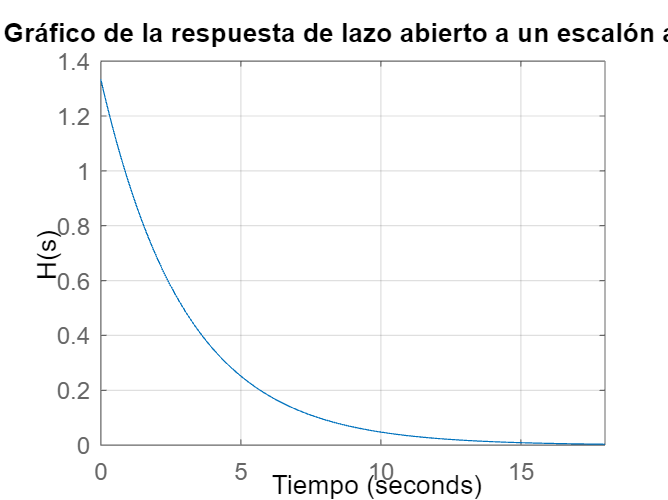

% Gráfico para el lazo abierto usando step()
figure;
step(H1A);
title("Gráfico de la respuesta de lazo abierto a un escalón a H1(s)")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");

Ahora se repite el mismo proceso para la respuesta de lazo cerrado.

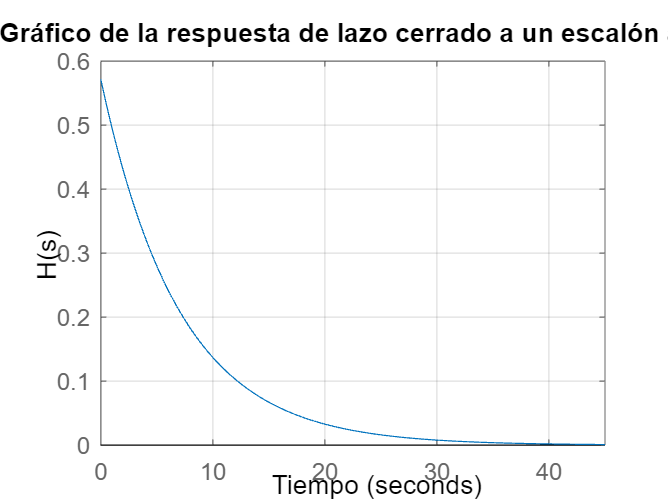

% Gráfico para el lazo cerrado usando step()
figure;
step(H1C);
title("Gráfico de la respuesta de lazo cerrado a un escalón a H1(s)")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");

Se calcula la ganancia estática para cada lazo, utilizando la función **dcgain.**

% Se calculan la ganancia estática de cada lazo.
K_H1A = dcgain(H1A)

K_H1A = 0

K_H1C = dcgain(H1C)

K_H1C = 0

s_H1A = struct with fields:
         RiseTime: 0
    TransientTime: 11.7362
     SettlingTime: NaN
      SettlingMin: 8.8092e-04
      SettlingMax: 1.3333
        Overshoot: Inf
       Undershoot: 0
             Peak: 1.3333
         PeakTime: 0


s_H1C = struct with fields:
         RiseTime: 0
    TransientTime: 27.3845
     SettlingTime: NaN
      SettlingMin: 3.7754e-04
      SettlingMax: 0.5714
        Overshoot: Inf
       Undershoot: 0
             Peak: 0.5714
         PeakTime: 0


Utilizando la función **zero()** se pueden obtener los ceros para cada lazo y utilizando la función **pole()** se obtienen los polos para cada lazo.

% Se obtienen los ceros y polos para cada lazo
ceros_H1A = zero(H1A)

ceros_H1A = 0

polos_H1A = pole(H1A)

polos_H1A = -0.3333


ceros_H1C = zero(H1C)

ceros_H1C = 0

polos_H1C = pole(H1C)

polos_H1C = -0.1429

## Función 2

Se debe realizar el mismo proceso que la función 1, por lo que en primer lugar se deben obtener las expresiones racionales correspondientes al lazo abierto y el lazo cerrado. Nuevamente, dada la naturaleza del sistema, H(s) corresponde al lazo abierto y se debe utilizar feedback() para encontrar la expresión racional del lazo cerrado.

% Se define la función de transferencia H(s) de la ecuación 2
H2 = (5*s^2 + 7*s + 1)/(s^2 + 6*s + 3);
% Lazo abierto corresponde a H(s)
H2A = H2

H2A =
 
  5 s^2 + 7 s + 1
  ---------------
   s^2 + 6 s + 3
 
Continuous-time transfer function.
Model Properties


% Se utiliza feedback para encontrar el lazo cerrado
H2C = feedback(H2, 1)

H2C =
 
  5 s^2 + 7 s + 1
  ----------------
  6 s^2 + 13 s + 4
 
Continuous-time transfer function.
Model Properties


Ahora, se realizan los gráficos correspondientes de respuesta a un escalón utilizando la función **step()**. En primer lugar se realiza el gráfico para la respuesta de lazo abierto.

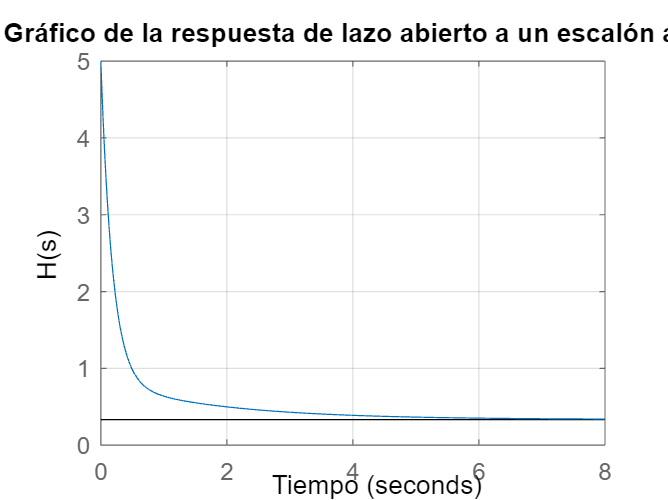

% Gráfico para el lazo abierto usando step()
figure;
step(H2A);
title("Gráfico de la respuesta de lazo abierto a un escalón a H2(s)")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");

Se repite el mismo proceso para la respuesta del lazo cerrado.

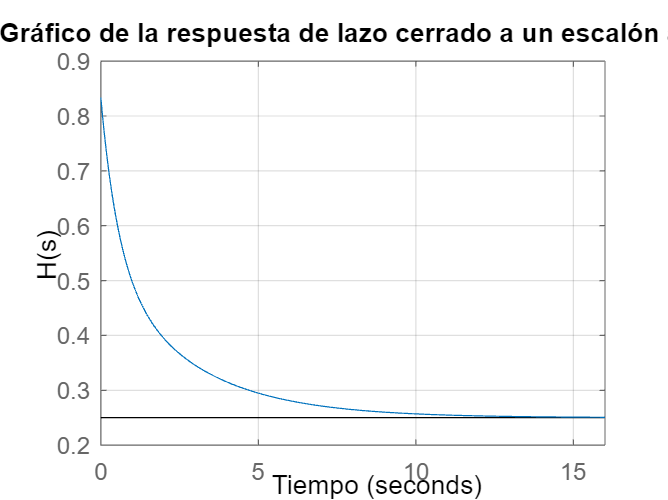

% Gráfico para el lazo cerrado usando step()
figure;
step(H2C);
title("Gráfico de la respuesta de lazo cerrado a un escalón a H2(s)")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");

Se calcula la ganancia estática para cada lazo.

% Se calcula la ganancia estática para ambos lazos
K_H2A = dcgain(H2A)

K_H2A = 0.3333

K_H2C = dcgain(H2C)

K_H2C = 0.2500

s_H2A = struct with fields:
         RiseTime: 0
    TransientTime: 3.0351
     SettlingTime: 7.8289
      SettlingMin: 0.3381
      SettlingMax: 5
        Overshoot: 1400
       Undershoot: 0
             Peak: 5
         PeakTime: 0


s_H2C = struct with fields:
         RiseTime: 0
    TransientTime: 8.6231
     SettlingTime: 10.9049
      SettlingMin: 0.2504
      SettlingMax: 0.8333
        Overshoot: 233.3333
       Undershoot: 0
             Peak: 0.8333
         PeakTime: 0


Finalmente, se obtienen los ceros y polos correspondientes a cada lazo.

% Se obtienen los ceros y polos para cada lazo
ceros_H2A = zero(H2A)

ceros_H2A =    -1.2385
   -0.1615


polos_H2A = pole(H2A)

polos_H2A =    -5.4495
   -0.5505



ceros_H2C = zero(H2C)

ceros_H2C =    -1.2385
   -0.1615


polos_H2C = pole(H2C)

polos_H2C =    -1.7953
   -0.3713
